# Проблема собственных значений в задаче Штурма-Лиувилля. Вариант 11.

## Введение

Дана следующая краевая задача:


$$((-kx+l)u')'+\left(k^2 \left(\frac{1}{kx+l} -kx\right)\right)u = \lambda u, k = 1.57495,\ l=11.74842 (1)
$$



$$u(-1)=u(1)=0 (2)
$$


Необходимо найти собственные числа и собственные функции.

## Верхние и нижние оценки для собственных чисел

### Идея 

Для нахождения верхней и нижней оценки необходимо найти собственные числа данного уравнения


$$-\hat p y'' + \hat q y = \lambda y$$


где $\hat p = \min\limits_{x\in(a,b)}(\max\limits_{x\in(a,b)}) p(x),\ \hat q = \min\limits_{x\in(a,b)}(\max\limits_{x\in(a,b)}) q(x)$ в зависимости от того, какую из оценок необходимо получить. Собственные функции будут иметь вид 


$$y(x) = C_1 cos(\nu x)+ C_2 sin(\nu x) (3)
$$


где $\nu = \sqrt\frac{\lambda - \hat q}{\hat p}$. Для поиска собственных функций необходимо подставить (3) в (2) и приравнять определитель системы к 0:


$$\left|\left\lbrack \begin{array}{cc}
\mathrm{cos}\left(\nu x\right) & -\mathrm{sin}\left(\nu x\right)\\
\mathrm{cos}\left(\nu x\right) & \mathrm{sin}\left(\nu x\right)
\end{array}\right\rbrack \right|=0$$


Имеем:


$$\sin(2\nu x)=0
$$


Таким образом, $\nu_k = \frac{\pi k}{2},\ k\in \mathbb{N} $.  При данном $\nu_k$, учитывая нашу краевую задачу, собственная функция $y_k(x)
$ имеет вид $y_k(x) = \frac{\cos(\nu_k x) }{\int\limits_{-1}^1\cos^2(\nu_k x)dx}$ при $k=2l+1
$ и $y_k(x) = \frac{\sin(\nu_k x) }{\int\limits_{-1}^1\sin^2(\nu_k x)dx}$ при $k=2l$ .  Собственые числа найдем по формуле: $\lambda_k = \nu_k^2\hat p+\hat q$.

### Реализация

 k = 1.57495;
 l = 11.74842;

В нашем случае, $p(x) = kx+l
$, $q(x) = k^2 \left(\frac{1}{kx+l} -kx\right)$. Поскольку p(x) - линейная функция, ее минимум и максимум достигаются на концах отрезка$(-1,1)$.

syms p x;
p = k*x + l;
min_p = subs(p,-1);
max_p = subs(p,1);

Функция $q(x)
$, напротив, убывает на $(-1,1)$, поэтому минимум достигается на левом конце, а максимум - на правом.

sym q;
q = k*k*(1/(k*x+l)-k*x);
min_q = subs(q,1);
max_q = subs(q,-1);

Соответственно, собственные функции для первого и второго собственного числа равны 

nu_1 = pi/2;
nu_2 = pi;
syms y_1 y_2;
y_1 = cos(nu_1*x)/dotprod(cos(nu_1*x),cos(nu_1*x));
y_2 = sin(nu_2*x)/dotprod(sin(nu_2*x),sin(nu_2*x));

Оценки для собственных чисел равны:

lambda_1_min = nu_1*nu_1 * min_p + min_q;
lambda_2_min = nu_2*nu_2*min_p + min_q;
lambda_1_max = nu_1*nu_1*max_p + max_q;
lambda_2_max = nu_2*nu_2*max_p + max_q;

Убедимся, что собственные функции удовлетворяют краевой задаче

subs(y_1,-1)

$$ans = 0.0$$

subs(y_1,1)

$$ans = 0.0$$

subs(y_2,-1)

$$ans = 0.0$$

subs(y_2,1)

$$ans = 0.0$$

Найдем невязку, подставив полученные выражения для $y_1,y_2$ и значения $\lambda_1,\lambda_2$ в (1), получим

first_errors = zeros(2,1);
first_errors(1) = dotprod(L(y_1)-lambda_1_min*y_1,L(y_1)-lambda_1_min*y_1);
first_errors(2) = dotprod(L(y_1)-lambda_1_max*y_1,L(y_1)-lambda_1_max*y_1);
second_errors = zeros(2,1);
second_errors(1) = dotprod(L(y_2)-lambda_2_min*y_2,L(y_2)-lambda_2_min*y_2);
second_errors(2) = dotprod(L(y_2)-lambda_2_max*y_2,L(y_2)-lambda_2_max*y_2);
evaluation_labels = {'Оценки lambda 1','Невязки lambda 1','Оценки для lambda 2','Невязки lambda 2'};
evaluation_table = table(double([lambda_1_min;lambda_1_max]),first_errors,double([lambda_2_min;lambda_2_max]),second_errors, ...
    'VariableNames',evaluation_labels)

evaluation_table = 2×4 table
    Оценки lambda 1    Невязки lambda 1    Оценки для lambda 2    Невязки lambda 2
    _______________    ________________    ___________________    ________________

        21.382              67.166               96.688                460.21     
        37.025              67.271               135.65                460.42     


## Приближенные значения первых двух собственных чисел

### Идея

Приближенные значения собственных чисел можно найти по формуле 


$$\lambda_i = \frac{[y_i,y_i]}{(y_i,y_i)}$$


где $[y,z] = \int\limits_{-1}^{1} (py'z' +qyz)dx$, $(y,z) = \int\limits_{-1}^{1} y\overline zdx$

### Реализация

Воспользуемся вспомогательными функциями 

lambda_1_appr = energprod(y_1,y_1)/dotprod(y_1,y_1)

$$lambda\_1\_appr = 29.199695144148177128329280094476$$

lambda_2_appr = energprod(y_2,y_2)/dotprod(y_2,y_2)

$$lambda\_2\_appr = 116.16447013161616297338696313091$$

## Метод Ритца

### Идея

Выберем ЛНЗ систему функций $\omega_i$ из $H_L$. Тогда задача на вариационный принцип Куранта сводится к алгебраической обобщенной задаче на собственные значения:


$$\Gamma_L c - \lambda \Gamma c=0$$


где $\Gamma = \{(\omega_i,\omega_j)\}_{i,j=1}^n$, $\Gamma_L = \{[\omega_i,\omega_j]\}_{i,j=1}^n$. 

В случае, если $\omega_j$ - ортогональная нормированная система, то задача сводится к нахождению собственных чисел матрицы $\Gamma_L$.

### Реализация

Поскольку наша краевая задача является задачей первого типа на обоих концах промежутка, в качестве ЛНЗ системы выберем функции 

$\omega_k(x) = (1-x^2)\hat P_{k-1}^{(2,2)}(x),\ k=1,2,\dots,n
$,

где $\hat P_i^{(2,2)}(x) = \frac{1}{4}\sqrt{\frac{(i+3)(i+4)(2i+5)}{2(i+1)(i+2)}}P_i^{(2,2)}(x)$, $P_i^{(2,2)}(x)$ - полиномы Якоби. 

Такая система будет ортогональной и нормированной.

Для построения матриц Ритца воспользуемся функцией ritz_matrices().

[G,G_L] = ritz_matrices(7);

**Примечание: **для построения набора координатных функций используются вспомогательные функции generate_coordinates и myJacobi()

Для поиска собственных чисел матрицы $\Gamma_L$ воспользуемся функцией встроенной функцией языка MATLAB

[vectors,lambdas] = eig(G_L);

Искомые собственные числа:

lambda_1_acc = lambdas(1,1)

lambda_1_acc = 29.1475

lambda_2_acc = lambdas(2,2)

lambda_2_acc = 115.7299

Как и ожидалось, полученные значения удовлетворяют ограничениям, полученным в пункте 1, и близки по значениям к результатам, полученным в пункте 2. 

## Метод обратных итераций

### Идея

Заметим, что $\lambda_{min}$ - собственное число матрицы $\Gamma^{-1} \Gamma_L$. Кроме того, справедливо 


$$\lambda_{min}(\Gamma^{-1}\Gamma_L) = \frac{1}{\lambda_{max}(\Gamma_L^{-1}\Gamma)}$$


Соответственно, мы можем найти $\lambda_{max}(\Gamma_L^{-1} \Gamma)$ методом скалярных произведений, и благодаря этому вычислить $\lambda_{min}(\Gamma^{-1}\Gamma_L)$.

**Примечание: **метод скалярных произведений был описан в [одной из предыдущих работ](https://github.com/SkyWaet/Numerical-Methods-3rd-year/tree/master/Eigenvalues%20problem). Его реализация находится в файле dotProdMethod.m

### Реализация

Используя готовую функцию dotProdMethod, вычислим необходимые приближения $\lambda_{min}$

% технические переменные, необходимые для заполнения таблицы
inv_iter_lambdas = zeros(5,1);
inv_iter_operator_error = zeros(5,1);
inv_iter_error = zeros(5,1);
inv_count = zeros(5,1);

for n=3:7
    inv_count(n-2) = n;
    % Матрицы Ритца
    [G,G_L,coordinates] = ritz_matrices(n);
    A = G_L^(-1)*G;
    
    % Поиск максимального по модулю собственного числа
    [lambda_max,c] = dotProdMethod(A);
    
    % Искомое приближение
    lambda_min = 1 / lambda_max;
    inv_iter_lambdas(n-2) = lambda_min;
    
    % Собственная функция, соответствующая искомому собственному числу
    y_n = y(c,coordinates);
    
    % Расчет погрешностей и невязок
    inv_iter_operator_error(n-2) = subs(L(y_n),x,0)-lambda_min*subs(y_n,x,0);
    inv_iter_error(n-2) = lambda_min - lambda_1_acc;
end

Оформим результаты в виде следующей таблицы

iter_labels = {'n','Lambda_1_n','Lambda_1_n - Lambda_1_acc','Ly - Lambda*y'};
inv_iter_table = table(inv_count,inv_iter_lambdas,inv_iter_error,inv_iter_operator_error, ...
    'VariableNames',iter_labels)

inv_iter_table = 5×4 table
    n    Lambda_1_n    Lambda_1_n - Lambda_1_acc    Ly - Lambda*y
    _    __________    _________________________    _____________

    3      29.149                0.00105               -0.34745  
    4      29.148             0.00041256               -0.32769  
    5      29.148             4.8126e-05              -0.091082  
    6      29.148             4.7784e-05              -0.090953  
    7      29.148             4.7723e-05              -0.090649  


## Выводы

Построим графики собственных функций

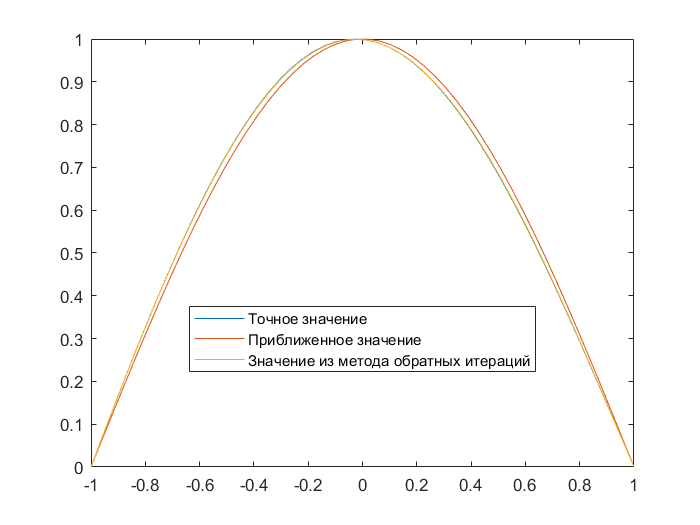

x = linspace(-1,1,50);
y_1_acc_val = subs(y(vectors(:,1),coordinates),x);
y_1_approx_val = subs(y_1,x);
y_1_iter_val = subs(y_n,x);
plot(x,y_1_acc_val)
hold on
plot(x,y_1_approx_val)
hold on
plot(x,y_1_iter_val)
hold off
lgd = legend('Точное значение', 'Приближенное значение','Значение из метода обратных итераций');
lgd.Location = "best";

Чтобы сделать различия более заметными, изменим масштаб.

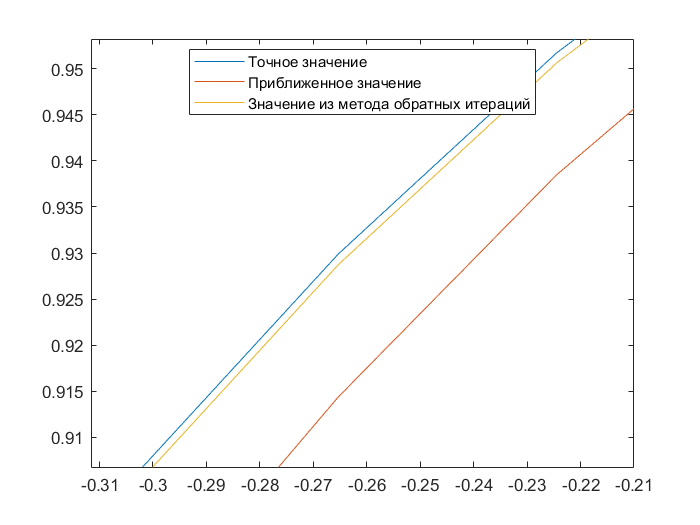

plot(x,y_1_acc_val)
hold on
plot(x,y_1_approx_val)
hold on
plot(x,y_1_iter_val)
hold off
lgd = legend('Точное значение', 'Приближенное значение','Значение из метода обратных итераций');
lgd.Location = "best";

xlim([-0.3116 -0.2100])
ylim([0.9068 0.9532])

Как мы можем заметить, решение, полученное методом обратных итераций, близко по значению к "точному" решению, полученному методом Ритца.

## Вспомогательные функции

function dotprod = dotprod(y,z) % Скалярное произведение в L2
    dotprod = vpaintegral(y*z,-1,1);
end
function energprod = energprod(y,z) % Энергетическое скалярное произведение  
     k = 1.57495;
    l = 11.74842;
    syms p x q;    
    p = k*x + l;
    q = k*k*(1/(k*x+l)-k*x);
    energprod = vpaintegral(p*diff(y)*diff(z)+q*y*z,-1,1);
end
function myJacobi = myJacobi(i) % Генератор полиномов Якоби
    syms x;
    myJacobi = 0.25*sqrt((i+3)*(i+4)*(2*i+5)/(2*(i+1)*(i+2)))*jacobiP(i,2,2,x);
end
function coordinate_functions = generate_coordinates(n) % Генератор координатных функций
    coordinate_functions = sym(zeros(n,1));
    syms x;
    for i=1:n      
        coordinate_functions(i,1)=(1-x^2)*myJacobi(i-1);
    end
end
function [G, G_L, coordinates] = ritz_matrices(n) % Генератор матриц Ритца
    G = zeros(n,n);
    G_L = zeros(n,n);
    coordinates = generate_coordinates(n);
    for i=1:n
        for j=1:n
            G(i,j) = dotprod(coordinates(i),coordinates(j));
            G_L(i,j) = energprod(coordinates(i),coordinates(j));
        end
    end
end
function L = L(y) % Дифференциальный оператор
    syms p x q; 
    k = 1.57495;
    l = 11.74842;
    q = k*k*(1/(k*x+l)-k*x);
    p = k*x + l;
    L = -diff(p*diff(y)) + q*y;
end
function y = y(c,coordinates) % Поиск приближения по собственному вектору
    syms x;
    y = 0;
    for i=1:size(c)
        y = y + c(i)*coordinates(i);
    end
end